# Simulation For Multi-agent Pose Estimation: Distributed Invariant Kalman Filter Based on Covariance Intersection 

*In this scripts, we only take the 5 agents case as an example. But we have tried our best to make scripts easy to extend to other scenes like more agents. You can feel free to use this simulation, but please refer to our work.*

When run this code at the first time, you can either choose to use our generated datasets (/dataset) or generate the data by yourself. In this work, we don't estimate ba and bg.

**How to generate dataset? **

- Open file "Scenes". 

- Run  "[generate_scene.mlx](matlab:open('/Scenes/generate_scene.mlx'))". You can modify the number of agents, trajectory, noise scale, graph structure and so on.

**We will compare the following methods:**

- Method 1: DInCIKFc. Distributed invariant Kalman filter based on covariance intersection using co-visible features.

- Method 2: DInCIKF. Distributed invariant Kalman filter based on covariance intersection without using co-visible features.

- Method 3: SciLie. Split covariance intersection on Lie group.

- Method 4: InEKF.  Using InEKF to fuse both independent and dependent sources of information.

- Method 5: Local odometry. Control group, test the results without communication.

**Evaluation metrics:** 

The evaluation results will be saved automatically in file "TestResults/[dataset name/]". The specific evaluation functions are in the file "Evaluation". 

- Absolute trajectory error~(ATE) curve and average ATE rmse for each agent's trajectoroies. ([ATE.m](matlab:open('/Evaluation/ATE.m')))

- Average ATE rmse of all agents ([ATE_ALL.m](matlab:open('/Evaluation/ATE_ALL.m')))

*Enjoy*.

Choose which method                                                                                                                                                                                       

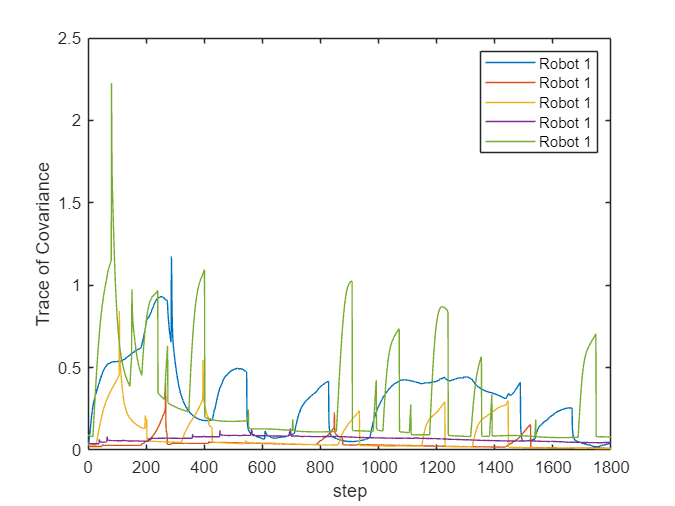

method 1


--------------/RMSE/-------------
Robots 


i = 1

Orientation(rad): 
Err_IMU_R | 0.0048611
Position(m):
Err_IMU_p | 0.28477
--------------/RMSE/-------------
Robots 


i = 2

Orientation(rad): 
Err_IMU_R | 0.0013677
Position(m):
Err_IMU_p | 0.065498
--------------/RMSE/-------------
Robots 


i = 3

Orientation(rad): 
Err_IMU_R | 0.0013396
Position(m):
Err_IMU_p | 0.066338
--------------/RMSE/-------------
Robots 


i = 4

Orientation(rad): 
Err_IMU_R | 0.0011268
Position(m):
Err_IMU_p | 0.066128
--------------/RMSE/-------------
Robots 


i = 5

Orientation(rad): 
Err_IMU_R | 0.0015603
Position(m):
Err_IMU_p | 0.097798
============/Average RMSE/===========
Average Rotation RMSE among Robots: 
0.0020511
Average Position RMSE among Robots: 
0.11611


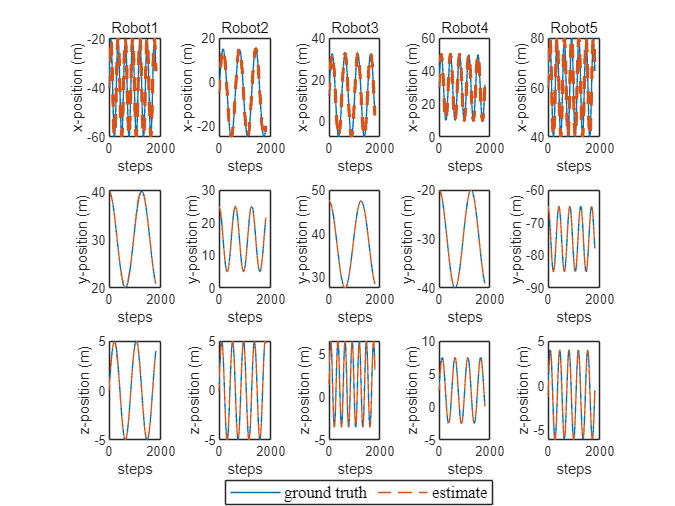

RERUN=1; % To decide if rerun of just draw the result. Only when there are data in the workspace, can you make this value 1.
if(RERUN)
clc;clear;
addpath(genpath(pwd));
datasetname='data_6666';   
datapath=['dataset\',datasetname,'.mat'];
load(datapath);

%      DInCIKFc|DInCIKF|SCILie|InEKF|Local  
Method=[1,         0,     0,     0,      0];
 
Method_N=length(find(Method));
agent_num=length(Robot);

## Initial Settings

### Initialization

method1=[];
method2=[];
method3=[];
method4=[];
method5=[];
N_imu=1;
N_mea=2;
t_update_set=[];
N_update_set=[];
N_ROBOTS=length(Robot);

% used to store all the results
activatedmethod=[];
tracelise_all=[];
actin=0;
%% Initial deviation
% IMU state initial error for 5 agen ts (We assume that they have the same bias for simplicity coding)
run_who=1;
bia_R_imu_angle=[0,0,0;
                 0,0,0;
                 0,0,0;
                 0,0,0;
                 0,0,0];
bia_p_imu =[0,0,0;
            0,0,0;
            0,0,0;
            0,0,0;
            0,0,0];
bia_v_imu = [0,0,0];
bia_b_a   = [0,0,0];
bia_b_g   = [0,0,0];

for ir=1:5
    bia_R_imu(ir).R = angle2dcm(bia_R_imu_angle(ir, 1), bia_R_imu_angle(ir, 2), bia_R_imu_angle(ir, 3));
end

initializer=[]; %structure to save the initial (X,P)
for i=1:N_ROBOTS
    initializer(i).X_init.Rimu=bia_R_imu(i).R*Robot(i).T_real0(1:3, 1:3);
    initializer(i).X_init.pimu=Robot(i).T_real0(1:3, 4)'+bia_p_imu(i,:);
    initializer(i).X_init.vimu=Robot(i).IMU_data(N_imu).v_inglobal_real+bia_v_imu;
    initializer(i).X_init.ba=b_a_real;
    initializer(i).X_init.bg=b_g_real ;
end

P_init=10^-3* eye(9);

#### Set noises

SIGMA_SET.sigma_a=sigma_a;
SIGMA_SET.sigma_g=sigma_g;
SIGMA_SET.sigma_bg=sigma_bg;
SIGMA_SET.sigma_ba=sigma_ba;
SIGMA_SET.sigma_cam=1;

## **Method 1: DInCIKFc**

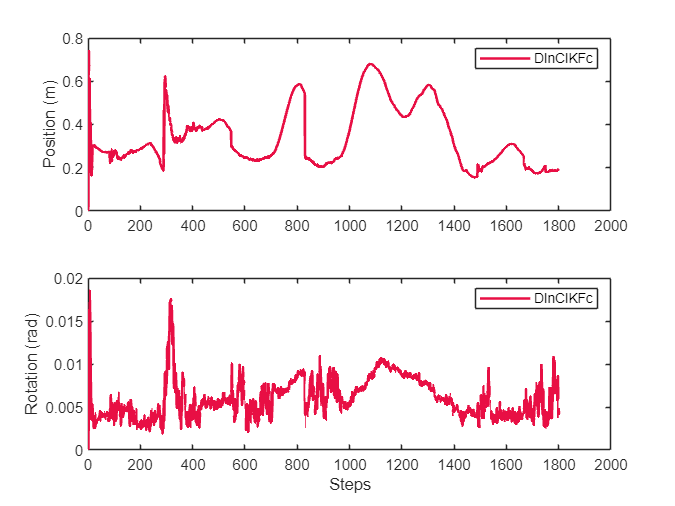

W_list = [];
TrPlist=[];

IF_VIO_UPDATE=0;
IF_CI=1;
IF_ESTIMATE_OBJ=1;
IF_CONSENSUS=1;

for i=1:N_ROBOTS          
    X_robots(i).objectlist=[];

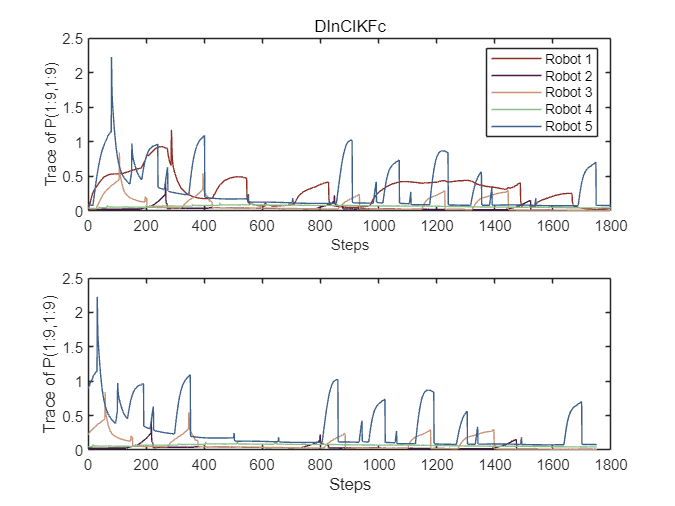

    X_robots(i).Tobj=[];
    X_robots(i).objinorder=[];
    

end
INIT=0;
if(Method(1))
    %%-------- INITIALIZE -------------
    N_imu=1;
    N_mea=2;
    N_cam=2;% Initial Count of camera measurement
    CAM_IF_UPDATE=0;% Value 1 means that new camera measurement is received.
    N_update=1;
    t_update_set(N_update)=0;
    N_update_set(N_update)=1;
    for i=1:N_ROBOTS  
        X_init=initializer(i).X_init;
        method1(i).X(N_update)=X_init;   
        method1(i).t(N_update)=0;    
        X_robots(i).X_last(N_imu).X=X_init;
        P_robots(i).P_last(N_imu).P=P_init;   
     % 存放加入了物体位姿估计的不确定性的协方差
    end
    
    t_imu=Robot(1).IMU_data(N_imu).t;

    NUM_CAM_UPDATE=zeros(5,1);
    %%-------- MAIN LOOP ---------------
    while(t_imu<T_WORKING)
        
        t_imu=Robot(1).IMU_data(N_imu).t; % Just use the 1st robot's timestamp
        %% 局部VIO
        %------预测------------------------------------------
        for i=1:N_ROBOTS
            X_last_i=X_robots(i).X_last(N_imu).X;
            P_last_i=P_robots(i).P_last(N_imu).P;
            IMU_data=Robot(i).IMU_data;
          
            acc_m=IMU_data(N_imu).a;
            w_m=IMU_data(N_imu).w;
            [X_pred, P_pred]=  inEKF_propagate(X_last_i, P_last_i, w_m, acc_m, dti, SIGMA_SET);
            %Note: once saving, should be saved as the next time dat
            X_robots(i).X_last(N_imu+1).X=X_pred;
            P_robots(i).P_last(N_imu+1).P=P_pred;
        end
        if(CAM_IF_UPDATE==1)%是否进行更新是由时间决定的。
            N_cam=N_cam+1;
            CAM_IF_UPDATE=0;
        end
  
        t_mea=m_data(N_mea).t;
        if(abs(t_imu-t_mea)<0.000000001)% meaning that receiving new pose measurements.
            N_update=N_update+1; % once receiving new measurements, conducting CI or KF update.
            %% 2.Using CI to fuse the dependent estimates
            method1(i).X(N_update)=X_robots(i).X_last(N_imu+1).X;
            method1(i).t(N_update)=t_imu; 
            if(IF_CI)
                COMMON_list=[];
                for i=1:agent_num % choose robot i.
                    nn=1;
                    real_Neighbornumber=length(find(A(:,i)))-1; % number of neighbors (denote j) of i. (without i itself)
                    est_xi=zeros(6,real_Neighbornumber);
                    P_est_by_j=zeros(6,6,real_Neighbornumber);
                    % --start "namespace: robot i"--
                    
                    for j_index=1:real_Neighbornumber % To get the measurement of j of i.
                       % if(~isempty(m_data(N_mea).robot(i).index))
                       j=m_data(N_mea).robot(i).index(j_index); % which j
                       Robot_mea_now=m_data(N_mea).robot(j); % Take out j's relative observation
                       
                       index_list_j=Robot_mea_now.index;
                       i_index = find(index_list_j==i);
                       X_m_i_in_j=Robot_mea_now.m_inter(i_index).m;
           
                       X_j_prior=eye(4,4);
                       X_j_prior(1:3,1:3)=X_robots(j).X_last(N_imu+1).X(1).Rimu;
                       X_j_prior(1:3,4)=X_robots(j).X_last(N_imu+1).X(1).pimu';
                       X_i_prior=eye(4,4);
                       X_i_prior(1:3,1:3)=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                       X_i_prior(1:3,4)=X_robots(i).X_last(N_imu+1).X(1).pimu';
                       X_i_est_by_j=X_j_prior * X_m_i_in_j;
    
                       inv_X_i_prior = invT(X_i_prior);
                       inv_X_i_est_by_j = invT(X_i_est_by_j); 
                       xi_now=se3_log(X_i_prior * inv_X_i_est_by_j);
                       est_xi(:,nn)=xi_now; 
                          
                       inv_X_i_in_j_mea=invT(X_m_i_in_j);
                       R_ji=sigma_ij(j)*sigma_ij(j)*eye(6);
                        
                       AdxJ = Adx(X_j_prior);
                       Theta =AdxJ * sigma_ij(j) *ones(6,1);
                       H_j = inv_J_left(Theta);
                       % H_j = inv(jacobian_left(Theta));
                       H_Rij = AdxJ;
    
                       P_est_res_now=P_robots(j).P_last(N_imu).P(1:6,1:6)  + H_Rij  *R_ji * H_Rij';
                       P_est_by_j(:,:,nn)=(P_est_res_now+P_est_res_now')/2;
                       nn=nn+1;

%%%%-----------------------------------Also fuse object-------------------
                        Neighbor_est_obj_list=X_robots(j).objinorder;
                        My_est_obj_list=X_robots(i).objinorder;
                  
                        Common_obj_list=intersect(Neighbor_est_obj_list, My_est_obj_list);
                        num_common=length(Common_obj_list);
                        

                        for lc=1:num_common
                            index_this_obj=Common_obj_list(lc);              
                            Xi_obj_order=X_robots(i).objinorder;

                            index_i=find( Xi_obj_order== index_this_obj);   
                            index_j=find(Neighbor_est_obj_list==index_this_obj);%该邻居中共识物体存放顺序。
                          
                            X_robots(i).Tobj(index_i).tofuse(end+1).T=X_robots(j).Tobj(index_j).T;
                            X_robots(i).Tobj(index_i).tofuse(end).P=P_robots(j).P_last(N_imu).P(9+6*(index_j-1)+1:9+6*(index_j), 9+6*(index_j-1)+1:9+6*(index_j) );
                            X_robots(i).Tobj(index_i).Pi=P_robots(i).P_last(N_imu).P(9+6*(index_i-1)+1:9+6*(index_i), 9+6*(index_i-1)+1:9+6*(index_i) );                          
                        end
                    end

                    %%%%Fusion of object

                    Pi=P_robots(i).P_last(N_imu+1).P;
                    [X_robots(i).Tobj, uplist]=Refine_obj_pose(X_robots(i).Tobj,1);
                   
                    if(IF_CONSENSUS)
                    LL=length(uplist);
                    else
                        LL=0;
                    end
                    if(LL)
                        dim = length(P_robots(i).P_last(N_imu+1).P);
                        a=zeros(dim,1);
                        cov_A = P_robots(i).P_last(N_imu+1).P;
                        [xi_CI,P_CI, w]=fastCI(est_xi,P_est_by_j);  
                        res = xi_CI;
                        B = P_CI; 
                        H = zeros(dim,6*LL+6);
                        H(1:6,1:6)=eye(6);

                        b=zeros(6*(LL+1), 1);
                        b(1:6,1)=res;
                        B=eye( 6*(LL+1),6*(LL+1)    );
                        B(1:6,1:6)=P_CI;
                        for zzzz=1:LL 
                            ob_index=uplist(zzzz);         
                            H(9+(ob_index-1)*6+1:9+(ob_index)*6, 6+(zzzz-1)*6+1:6+zzzz*6)=eye(6);
                            b(6+(zzzz-1)*6+1: 6+(zzzz)*6, 1)  = se3_log( X_robots(i).Tobj(ob_index).T * invT(   X_robots(i).Tobj(ob_index).Tfused ));
                            cha=norm(  b(6+(zzzz-1)*6+1: 6+(zzzz)*6, 1) );
                            B(6+(zzzz-1)*6+1: 6+(zzzz)*6, 6+(zzzz-1)*6+1: 6+(zzzz)*6)=X_robots(i).Tobj(ob_index).Pfused;
                        end
                    else

                        dim = length(P_robots(i).P_last(N_imu+1).P);
                        a=zeros(dim,1);
                        cov_A = P_robots(i).P_last(N_imu+1).P;
                        %---first to fuse pseudo i's pose mesurements from neighbors based on fast CI--
                        [xi_CI,P_CI, w]=fastCI(est_xi,P_est_by_j);        
                        b = xi_CI;
                        B = P_CI; 
                        H = zeros(dim,6);
                        H(1:6,1:6)=eye(6);
                    end
                    %---then fuse with prior estimation by solving the optimization problem-----
                    [c,C,omega]=conventionalCI(a,cov_A,b,B,H');  
                  
                    P_robots(i).P_last(N_imu+1).P=C;    
                    c=-c;
                    dR=c(1:3);
                    dP=c(4:6);
                    dV=c(7:9);
                    exp_dX1=[so3_exp(dR),jaco_left(dR)*dP,jaco_left(dR)*dV;zeros(2,3),eye(2)];%5*5
                    Rimu=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                    pimu=X_robots(i).X_last(N_imu+1).X(1).pimu;
                    vimu=X_robots(i).X_last(N_imu+1).X(1).vimu;
                    update_temp_IMU=exp_dX1*[Rimu, pimu', vimu';  zeros(2,3),eye(2,2)];

                    num_est_now = length(X_robots(i).objectlist);
                    if(num_est_now)
                        for zz=1:num_est_now
                            dT = c(9+(zz-1)* 6+1: 9+(zz-1)* 6+6  );
                            exp_dXo  =  se3_exp(dT);
                            X_robots(i).Tobj(zz).T= exp_dXo*X_robots(i).Tobj(zz).T;
                        end
                    end
                    method1(i).X(N_update).Rimu=update_temp_IMU(1:3,1:3);
                    method1(i).X(N_update).pimu=update_temp_IMU(1:3,4)';
                    method1(i).t(N_update)=t_imu; 
                    X_robots(i).X_last(N_imu+1).X(1).Rimu=update_temp_IMU(1:3,1:3); % if CI, rewrite.
                    X_robots(i).X_last(N_imu+1).X(1).pimu=update_temp_IMU(1:3,4)';
                    X_robots(i).X_last(N_imu+1).X(1).vimu=update_temp_IMU(1:3,5)';

                end
            end


            %%4. Consensus on object estimation among neighbors
            
            for i=1:N_ROBOTS

                mea_now=m_data(N_mea).robot(i);
                % --start "namespace: robot i"--
                num_see_feature=m_data(N_mea).robot(i).feature_flag;

                X_update=X_robots(i).X_last(N_imu+1).X;
                if(IF_ESTIMATE_OBJ)
                    if(num_see_feature)% only if seeing the feature, would the robot update
                        T_mea_feature=m_data(N_mea).robot(i).m_feature; 
                        index_i_see=m_data(N_mea).robot(i).indexlist;

                        %% Initialization of feature state
                        %% 对状态的更新增加
                        new_union = union(X_robots(i).objectlist,index_i_see);
                        new_object_list =  setdiff(new_union,X_robots(i).objectlist);
                        X_robots(i).objectlist =new_union;
                        new_union=[];%及时清零，因为下一次还会赋值。否则影响其他机器人
                        if(~isempty(new_object_list))   %如果有之前没有估计过的目标位姿，开启初始化            
                            for zz=1:length(new_object_list)
                                %新加入的特征对应的编号
                                INIT=1;
                                new_obj_index=new_object_list(zz);
                            
                                %找到该从未被初始化的特征，在该时刻测量的indexlist是哪个位置
                                index_num = find(index_i_see==new_obj_index);                
                                T_i = eye(4);
                                T_i(1:3,1:3)=X_update.Rimu;
                                T_i(1:3,4) = X_update.pimu';
                                X_robots(i).Tobj(end+1).T = T_i * T_mea_feature(index_num).T;
                                X_robots(i).objinorder(end+1) = new_obj_index; %请注意这里的顺序是和看到的先后有关的！
                                %初始化：
                                R_if = sigma_if(i) * sigma_if(i) * eye(6);
                                before_aug_Dimension = length(P_robots(i).P_last(N_imu+1).P);
                                
                                P_robots(i).P_last(N_imu+1).P = [P_robots(i).P_last(N_imu+1).P, zeros(before_aug_Dimension,6);  
                                         zeros(before_aug_Dimension,6)',P_robots(i).P_last(N_imu+1).P(1:6,1:6)+R_if];
                                
                                Jd = zeros(6,before_aug_Dimension);
                                Jd(1:6,1:6) = eye(6);

                                Daa =length(P_robots(i).P_last(N_imu+1).P); %The dimension after the augment!
                                P_i_now = P_robots(i).P_last(N_imu+1).P(1:before_aug_Dimension,1:before_aug_Dimension);
                                P_if= P_i_now * Jd'; % 9*9*9*6 = 9*6
                                P_robots(i).P_last(N_imu+1).P(1:before_aug_Dimension, before_aug_Dimension+1:before_aug_Dimension+6)  = P_if;
                                P_robots(i).P_last(N_imu+1).P( before_aug_Dimension+1:before_aug_Dimension+6,1:before_aug_Dimension) =P_if'; 
                                X_robots(i).Tobj(end).tofuse=[];
                            end
                        end

                        X_pred=X_robots(i).X_last(N_imu+1).X; % after CI
                        X_object = X_robots(i).Tobj; 
                        obj_order = X_robots(i).objinorder;
                        P_pred=P_robots(i).P_last(N_imu+1).P;
                        P_update=P_pred;
                        X_update=X_pred;
                        X_object_update=X_object;
                        if(~INIT)
                            [X_update,P_update, X_object_update]=inEKF_X_iter_update(X_pred, P_pred, X_object, obj_order, T_mea_feature, sigma_if(i), num_see_feature);
                        end
                        P_update=(P_update+P_update')/2;
                        % if update, rewrite.
                        X_robots(i).X_last(N_imu+1).X=X_update;
                      
                        X_robots(i).Tobj=X_object_update;
                        P_robots(i).P_last(N_imu+1).P=P_update;

                        method1(i).X(N_update)=X_update;
                        method1(i).t(N_update)=t_imu; 
                        INIT=0;
                    end
                end
                method1(i).X(N_update)=X_update;
                method1(i).t(N_update)=t_imu; 
                % --end "namespace: robot i"--
                TrPlist(i).P(N_update)=trace(P_robots(i).P_last(N_imu+1).P);
                   method1(i).Xobj=X_robots(i).Tobj;
        method1(i).obj_inorder=X_robots(i).objinorder;
            end      
            N_update_set(N_update)=N_imu;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;

        end
        N_imu=N_imu+1;
        CAM_IF_UPDATE=0;
    end
    actin=actin+1;
    activatedmethod(actin).methodname='DInCIKFc';
    activatedmethod(actin).result=method1;
    tracelise_all(actin).tracelist=TrPlist;
%%%%%%%%%%%%%%Single Evaluation%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    real_path_all=[];
    for i=1:N_ROBOTS
        real_path=Robot(i).real_path;
        real_path_select = filterArrayByIndex(real_path,N_update_set);
        real_path_all(i).rp=real_path_select;
    end
    figure()
    len = size(TrPlist(1).P,2);
    step = 1:len-1;
    for mee=1:agent_num
        roboname=['Robot', num2str(mee)];
    plot(step, TrPlist(mee).P(1,2:end), "DisplayName", 'Robot 1');hold on

    end
    xlabel("step");
    ylabel('Trace of Covariance');
    legend
%----------------------
    figure();
    disp("method 1");
    ATEsave(real_path_all, method1, landmarks, Eff_Range,1,datasetname);

end


### Method 2: DInCIKF

W_list = [];
TrPlist=[];

IF_VIO_UPDATE=0;
IF_CI=1;
IF_ESTIMATE_OBJ=1;
IF_CONSENSUS=0;


for i=1:N_ROBOTS          
    X_robots(i).objectlist=[];
    X_robots(i).Tobj=[];
    X_robots(i).objinorder=[];
    
end
INIT=0;
if(Method(2))   
    % run_who=run_who+1;
    % waitbar(run_who/Method_N,h );
    %%-------- INITIALIZE -------------
    N_imu=1;
    N_mea=2;
    N_cam=2;% Initial Count of camera measurement
    CAM_IF_UPDATE=0;% Value 1 means that new camera measurement is received.
    N_update=1;
    t_update_set(N_update)=0;
    N_update_set(N_update)=1;
    for i=1:N_ROBOTS  
        X_init=initializer(i).X_init;
        method2(i).X(N_update)=X_init;    
        method2(i).t(N_update)=0; 
        X_robots(i).X_last(N_imu).X=X_init;
        P_robots(i).P_last(N_imu).P=P_init;   
     % 存放加入了物体位姿估计的不确定性的协方差
    end
    
    t_imu=Robot(1).IMU_data(N_imu).t;

    NUM_CAM_UPDATE=zeros(5,1);
    %%-------- MAIN LOOP ---------------
    while(t_imu<T_WORKING)
        
        t_imu=Robot(1).IMU_data(N_imu).t; % Just use the 1st robot's timestamp
        %% 局部VIO
        %------预测------------------------------------------
        for i=1:N_ROBOTS
            X_last_i=X_robots(i).X_last(N_imu).X;
            P_last_i=P_robots(i).P_last(N_imu).P;
            IMU_data=Robot(i).IMU_data;
      
            acc_m=IMU_data(N_imu).a;
            w_m=IMU_data(N_imu).w;
            [X_pred, P_pred]=  inEKF_propagate(X_last_i, P_last_i, w_m, acc_m, dti, SIGMA_SET);
            %Note: once saving, should be saved as the next time dat
      
            X_robots(i).X_last(N_imu+1).X=X_pred;
            P_robots(i).P_last(N_imu+1).P=P_pred;
            
        %----Visual update-------------------------------------
            if(0)    
                camera_data=Robot(i).camera_data;
                t_cam=camera_data(N_cam).timestamp;
                X_object_update=X_robots(i).Tobj;
                X_object=X_robots(i).Tobj;
                if ((abs(t_cam-t_imu)<0.0000001))
                    CAM_IF_UPDATE=1;
                    camera_measure_now=camera_data(N_cam);
                    number_of_features_seen = length(camera_measure_now.uv); 
                    itermax=1;
                    if(number_of_features_seen>0)
                  
                    [X_esti, P_esti, X_object_update]=inEKF_iter_update(X_pred, P_pred, CAM_IF_UPDATE,acc_m,w_m,camera_measure_now, SIGMA_SET, itermax,CAM_INTRISIC, p_camera_in_IMU_real, R_camera_in_IMU_real,X_object);
                    X_robots(i).X_last(N_imu+1).X=X_esti;
                    P_robots(i).P_last(N_imu+1).P=P_esti;
                    X_robots(i).Tobj=X_object_update;
                    NUM_CAM_UPDATE(i,1)=NUM_CAM_UPDATE(i,1)+1;
                    end
                end           
            end  
        end
        if(CAM_IF_UPDATE==1)%是否进行更新是由时间决定的。
            N_cam=N_cam+1;
            CAM_IF_UPDATE=0;
        end

   
       
        t_mea=m_data(N_mea).t;
        if(abs(t_imu-t_mea)<0.000000001)% meaning that receiving new pose measurements.
            N_update=N_update+1; % once receiving new measurements, conducting CI or KF update.
            %% 2.Using CI to fuse the dependent estimates
            method2(i).X(N_update)=X_robots(i).X_last(N_imu+1).X;
            method2(i).t(N_update)=t_imu; 
            if(IF_CI)
                COMMON_list=[];
                for i=1:agent_num % choose robot i.
                    nn=1;
                    real_Neighbornumber=length(find(A(i,:)))-1; % number of neighbors (denote j) of i. (without i itself)
                    est_xi=zeros(6,real_Neighbornumber);
                    P_est_by_j=zeros(6,6,real_Neighbornumber);
                    % --start "namespace: robot i"--
                    
                    for j_index=1:real_Neighbornumber % To get the measurement of j of i.
                       
                       j=m_data(N_mea).robot(i).index(j_index); % which j
                       Robot_mea_now=m_data(N_mea).robot(j); % Take out j's relative observation
                       
                       index_list_j=Robot_mea_now.index;
                       i_index = find(index_list_j==i);
                       X_m_i_in_j=Robot_mea_now.m_inter(i_index).m;
           
                       X_j_prior=eye(4,4);
                       X_j_prior(1:3,1:3)=X_robots(j).X_last(N_imu+1).X(1).Rimu;
                       X_j_prior(1:3,4)=X_robots(j).X_last(N_imu+1).X(1).pimu';
                       X_i_prior=eye(4,4);
                       X_i_prior(1:3,1:3)=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                       X_i_prior(1:3,4)=X_robots(i).X_last(N_imu+1).X(1).pimu';
                       X_i_est_by_j=X_j_prior * X_m_i_in_j;
    
                       inv_X_i_prior = invT(X_i_prior);
                       inv_X_i_est_by_j = invT(X_i_est_by_j); 
                       xi_now=se3_log(X_i_prior * inv_X_i_est_by_j);
                       est_xi(:,nn)=xi_now; 
                          
                       inv_X_i_in_j_mea=invT(X_m_i_in_j);
                       R_ji=sigma_ij(j)*sigma_ij(j)*eye(6);
                        
                       AdxJ = Adx(X_j_prior);
                       Theta =AdxJ * sigma_ij(j) *ones(6,1);
                       H_j = inv_J_left(Theta);
                       % H_j = inv(jacobian_left(Theta));
                       H_Rij = AdxJ;
    
                       P_est_res_now=P_robots(j).P_last(N_imu).P(1:6,1:6)  + H_Rij  *R_ji * H_Rij';
                       P_est_by_j(:,:,nn)=(P_est_res_now+P_est_res_now')/2;
                       nn=nn+1;


%%%%%%%%%%%%%%%%%%%%%%%%%%Also fuse object
                        Neighbor_est_obj_list=X_robots(j).objinorder;
                        My_est_obj_list=X_robots(i).objinorder;
                  
                        Common_obj_list=intersect(Neighbor_est_obj_list, My_est_obj_list);
                        num_common=length(Common_obj_list);
                        

                        for lc=1:num_common
                            index_this_obj=Common_obj_list(lc);              
                            Xi_obj_order=X_robots(i).objinorder;

                            index_i=find( Xi_obj_order== index_this_obj);   
                            index_j=find(Neighbor_est_obj_list==index_this_obj);%该邻居中共识物体存放顺序。
                           

                            X_robots(i).Tobj(index_i).tofuse(end+1).T=X_robots(j).Tobj(index_j).T;
                            X_robots(i).Tobj(index_i).tofuse(end).P=P_robots(j).P_last(N_imu).P(9+6*(index_j-1)+1:9+6*(index_j), 9+6*(index_j-1)+1:9+6*(index_j) );
                            X_robots(i).Tobj(index_i).Pi=P_robots(i).P_last(N_imu).P(9+6*(index_i-1)+1:9+6*(index_i), 9+6*(index_i-1)+1:9+6*(index_i) );
                           
                        end


   
                    end

                    %%%%Fusion of object
                    Pi=P_robots(i).P_last(N_imu+1).P;
                    [X_robots(i).Tobj, uplist]=Refine_obj_pose(X_robots(i).Tobj,1);
            
                    if(IF_CONSENSUS)
                    LL=length(uplist);
                    else
                        LL=0;
                    end
                    if(LL)
                        dim = length(P_robots(i).P_last(N_imu+1).P);
                        a=zeros(dim,1);
                        cov_A = P_robots(i).P_last(N_imu+1).P;
                        [xi_CI,P_CI, w]=fastCI(est_xi,P_est_by_j);  
                        res = xi_CI;
                        B = P_CI; 
                        H = zeros(dim,6*LL+6);
                        H(1:6,1:6)=eye(6);

                        b=zeros(6*(LL+1), 1);
                        b(1:6,1)=res;
                        B=eye( 6*(LL+1),6*(LL+1)    );
                        B(1:6,1:6)=P_CI;
                        for zzzz=1:LL 
                            ob_index=uplist(zzzz);

          
                            H(9+(ob_index-1)*6+1:9+(ob_index)*6, 6+(zzzz-1)*6+1:6+zzzz*6)=eye(6);
                            
                            b(6+(zzzz-1)*6+1: 6+(zzzz)*6, 1)  = se3_log( X_robots(i).Tobj(ob_index).T * invT(   X_robots(i).Tobj(ob_index).Tfused ));
                            cha=norm(  b(6+(zzzz-1)*6+1: 6+(zzzz)*6, 1) );
                            B(6+(zzzz-1)*6+1: 6+(zzzz)*6, 6+(zzzz-1)*6+1: 6+(zzzz)*6)=X_robots(i).Tobj(ob_index).Pfused;
                        end
                       
                        
                    else

                        dim = length(P_robots(i).P_last(N_imu+1).P);
                        a=zeros(dim,1);
                        cov_A = P_robots(i).P_last(N_imu+1).P;
                        %---first to fuse pseudo i's pose mesurements from neighbors based on fast CI--
                        [xi_CI,P_CI, w]=fastCI(est_xi,P_est_by_j);        
                        b = xi_CI;
                        B = P_CI; 
                        H = zeros(dim,6);
                        H(1:6,1:6)=eye(6);
                    end
                    %---then fuse with prior estimation by solving the optimization problem-----
                    [c,C,omega]=conventionalCI(a,cov_A,b,B,H');  
                  
                    P_robots(i).P_last(N_imu+1).P=C;    
                    c=-c;
                    dR=c(1:3);
                    dP=c(4:6);
                    dV=c(7:9);
                    exp_dX1=[so3_exp(dR),jaco_left(dR)*dP,jaco_left(dR)*dV;zeros(2,3),eye(2)];%5*5
                    Rimu=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                    pimu=X_robots(i).X_last(N_imu+1).X(1).pimu;
                    vimu=X_robots(i).X_last(N_imu+1).X(1).vimu;
                    update_temp_IMU=exp_dX1*[Rimu, pimu', vimu';  zeros(2,3),eye(2,2)];

                    num_est_now = length(X_robots(i).objectlist);
                    if(num_est_now)
                        for zz=1:num_est_now
                            dT = c(9+(zz-1)* 6+1: 9+(zz-1)* 6+6  );
                            exp_dXo  =  se3_exp(dT);
                            X_robots(i).Tobj(zz).T= exp_dXo*X_robots(i).Tobj(zz).T;
                        end

                    end
                   

                method2(i).X(N_update).Rimu=update_temp_IMU(1:3,1:3);
                method2(i).t(N_update)=t_imu; 
                method2(i).X(N_update).pimu=update_temp_IMU(1:3,4)';

                X_robots(i).X_last(N_imu+1).X(1).Rimu=update_temp_IMU(1:3,1:3); % if CI, rewrite.
                X_robots(i).X_last(N_imu+1).X(1).pimu=update_temp_IMU(1:3,4)';
                X_robots(i).X_last(N_imu+1).X(1).vimu=update_temp_IMU(1:3,5)';


                end
            end


            %%4. Consensus on object estimation among neighbors
            
            for i=1:N_ROBOTS


                mea_now=m_data(N_mea).robot(i);
                % --start "namespace: robot i"--
                num_see_feature=m_data(N_mea).robot(i).feature_flag;

                X_update=X_robots(i).X_last(N_imu+1).X;
                if(IF_ESTIMATE_OBJ)
                    if(num_see_feature)% only if seeing the feature, would the robot update
                        T_mea_feature=m_data(N_mea).robot(i).m_feature; 
                        index_i_see=m_data(N_mea).robot(i).indexlist;

                        %% Initialization of feature state
                        %% 对状态的更新增加
                        new_union = union(X_robots(i).objectlist,index_i_see);
                        new_object_list =  setdiff(new_union,X_robots(i).objectlist);
                        X_robots(i).objectlist =new_union;
                        new_union=[];%及时清零，因为下一次还会赋值。否则影响其他机器人
                        if(~isempty(new_object_list))   %如果有之前没有估计过的目标位姿，开启初始化            
                            for zz=1:length(new_object_list)
                                %新加入的特征对应的编号
                                INIT=1;
                                new_obj_index=new_object_list(zz);
                            
                                %找到该从未被初始化的特征，在该时刻测量的indexlist是哪个位置
                                index_num = find(index_i_see==new_obj_index);                
                                T_i = eye(4);
                                T_i(1:3,1:3)=X_update.Rimu;
                                T_i(1:3,4) = X_update.pimu';
                                X_robots(i).Tobj(end+1).T = T_i * T_mea_feature(index_num).T;
                                X_robots(i).objinorder(end+1) = new_obj_index; %请注意这里的顺序是和看到的先后有关的！
                                %初始化：
                                R_if = sigma_if(i) * sigma_if(i) * eye(6);
                                before_aug_Dimension = length(P_robots(i).P_last(N_imu+1).P);
                                
                                P_robots(i).P_last(N_imu+1).P = [P_robots(i).P_last(N_imu+1).P, zeros(before_aug_Dimension,6);  
                                         zeros(before_aug_Dimension,6)',P_robots(i).P_last(N_imu+1).P(1:6,1:6)+R_if];
                              
                                
                                Jd = zeros(6,before_aug_Dimension);
                                Jd(1:6,1:6) = eye(6);


                                Daa =length(P_robots(i).P_last(N_imu+1).P); %The dimension after the augment!
                                P_i_now = P_robots(i).P_last(N_imu+1).P(1:before_aug_Dimension,1:before_aug_Dimension);
                                P_if= P_i_now * Jd'; % 9*9*9*6 = 9*6
                                P_robots(i).P_last(N_imu+1).P(1:before_aug_Dimension, before_aug_Dimension+1:before_aug_Dimension+6)  = P_if;
                                P_robots(i).P_last(N_imu+1).P( before_aug_Dimension+1:before_aug_Dimension+6,1:before_aug_Dimension) =P_if'; 
                                X_robots(i).Tobj(end).tofuse=[];
                            end
                        end




                        X_pred=X_robots(i).X_last(N_imu+1).X; % after CI
                        X_object = X_robots(i).Tobj; 
                        obj_order = X_robots(i).objinorder;
                        P_pred=P_robots(i).P_last(N_imu+1).P;
                        P_update=P_pred;
                        X_update=X_pred;
                        X_object_update=X_object;
                        if(~INIT)
                            [X_update,P_update, X_object_update]=inEKF_X_iter_update(X_pred, P_pred, X_object, obj_order, T_mea_feature, sigma_if(i), num_see_feature);
                        end
                        P_update=(P_update+P_update')/2;
                        % if update, rewrite.
                        X_robots(i).X_last(N_imu+1).X=X_update;
                      
                        X_robots(i).Tobj=X_object_update;
                        P_robots(i).P_last(N_imu+1).P=P_update;

                        method2(i).X(N_update)=X_update;
                        method2(i).t(N_update)=t_imu; 
                        INIT=0;
                    end
                end
                method2(i).X(N_update)=X_update;
                % --end "namespace: robot i"--
                TrPlist(i).P(N_update)=trace(P_robots(i).P_last(N_imu+1).P);
                method2(i).Xobj=X_robots(i).Tobj;
                method2(i).obj_inorder=X_robots(i).objinorder;
            end
        
            
            
            N_update_set(N_update)=N_imu;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;

        end
        N_imu=N_imu+1;
        CAM_IF_UPDATE=0;
    end
actin=actin+1;
activatedmethod(actin).methodname='DInCIKF';
activatedmethod(actin).result=method2;
tracelise_all(actin).tracelist=TrPlist;
end



if(Method(2))
    real_path_all=[];
    for i=1:N_ROBOTS
        real_path=Robot(i).real_path;
        real_path_select = filterArrayByIndex(real_path,N_update_set);
        real_path_all(i).rp=real_path_select;
    end
    figure()
    len = size(TrPlist(1).P,2);
    step = 1:len-1;
    for mee=1:agent_num
        roboname=['Robot', num2str(mee)];
    plot(step, TrPlist(mee).P(1,2:end), "DisplayName", 'Robot 1');hold on

    end
    xlabel("step");
    ylabel('Trace of Covariance');
    legend();
    figure();
    disp("method 2");
    ATE(real_path_all, method2, landmarks, Eff_Range,2,datasetname);
end



## Split covariance intersection on Lie group

W_list = [];
TrPlist=[];
IF_VIO_UPDATE=0;
IF_CI=1;
IF_ESTIMATE_OBJ=1;
IF_CONSENSUS=0;

for i=1:N_ROBOTS          
    X_robots(i).objectlist=[];
    X_robots(i).Tobj=[];
    X_robots(i).objinorder=[];
    
end
INIT=0;
if(Method(3))
    %    run_who=run_who+1;
    % waitbar(run_who/Method_N,h );
    %%-------- INITIALIZE -------------
    N_imu=1;
    N_mea=2;
    N_cam=2;% Initial Count of camera measurement
    CAM_IF_UPDATE=0;% Value 1 means that new camera measurement is received.
    N_update=1;
    t_update_set(N_update)=0;  
    N_update_set(N_update)=1;
    for i=1:N_ROBOTS  
        X_init=initializer(i).X_init;
        method3(i).X(N_update)=X_init;  
        method3(i).t(N_update)=0;
        X_robots(i).X_last(N_imu).X=X_init;
        P_robots(i).P_last(N_imu).Pindep=10e-4*eye(9);   % SCI需要记录两套协方差
        P_robots(i).P_last(N_imu).Pdep=10e-4*eye(9); 
        P_robots(i).P_last(N_imu).P=P_robots(i).P_last(N_imu).Pdep+P_robots(i).P_last(N_imu).Pindep; 
     % 存放加入了物体位姿估计的不确定性的协方差
    end
    
    t_imu=Robot(1).IMU_data(N_imu).t;

    NUM_CAM_UPDATE=zeros(5,1);
    %%-------- MAIN LOOP ---------------
    while(t_imu<T_WORKING)
        t_imu=Robot(1).IMU_data(N_imu).t; % Just use the 1st robot's timestamp
    %------------------------------预测------------------------------------------
        for i=1:N_ROBOTS
            X_last_i=X_robots(i).X_last(N_imu).X;
            P_last_i=P_robots(i).P_last(N_imu);
            IMU_data=Robot(i).IMU_data;
            camera_data=Robot(i).camera_data;
            acc_m=IMU_data(N_imu).a;
            w_m=IMU_data(N_imu).w;
            [X_pred, P_pred]=  SCI_Liegroup_propagate(X_last_i, P_last_i, w_m, acc_m, dti, SIGMA_SET);
            X_robots(i).X_last(N_imu+1).X=X_pred;
            P_robots(i).P_last(N_imu+1)=P_pred;
        end

    %------------------------------更新-----------------------------------------------
        t_mea=m_data(N_mea).t;
        if(abs(t_imu-t_mea)<0.000000001)% meaning that receiving new pose measurements.
            N_update=N_update+1; % once receiving new measurements, conducting CI or KF update.
    %................用CI融合邻居对i的估计。。。。。。。。。。。。。。。。。。。。。。。。。。。。。。。。。。。。。。
            method3(i).X(N_update)=X_robots(i).X_last(N_imu+1).X;
            method3(i).t(N_update)=t_imu;
            if(IF_CI)
                COMMON_list=[];
                for i=1:agent_num % choose robot i.
                    nn=1;
                    real_Neighbornumber=length(find(A(i,:)))-1; % number of neighbors (denote j) of i. (without i itself)
                    est_xi=zeros(6,real_Neighbornumber);
                    P_est_by_j=zeros(6,6,real_Neighbornumber);
                    T_fusej=[];

               %% 得到j对i估计的位姿的融合     
                    for j_index=1:real_Neighbornumber % To get the measurement of j of i.
                       
                       j=m_data(N_mea).robot(i).index(j_index); % which j
                       Robot_mea_now=m_data(N_mea).robot(j); % Take out j's relative observation
                       
                       index_list_j=Robot_mea_now.index;
                       i_index = find(index_list_j==i);
                       X_m_i_in_j=Robot_mea_now.m_inter(i_index).m;
           
                       X_j_prior=eye(4,4);
                       X_j_prior(1:3,1:3)=X_robots(j).X_last(N_imu+1).X(1).Rimu;
                       X_j_prior(1:3,4)=X_robots(j).X_last(N_imu+1).X(1).pimu';
                       X_i_prior=eye(4,4);
                       X_i_prior(1:3,1:3)=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                       X_i_prior(1:3,4)=X_robots(i).X_last(N_imu+1).X(1).pimu';
                       X_i_est_by_j=X_j_prior * X_m_i_in_j;
                        
                       T_fusej(j_index).T=X_i_est_by_j;


                       inv_X_i_prior = invT(X_i_prior);
                       inv_X_i_est_by_j = invT(X_i_est_by_j); 
                       xi_now=se3_log(X_i_prior * inv_X_i_est_by_j);
                       est_xi(:,nn)=xi_now; 
                          
                       inv_X_i_in_j_mea=invT(X_m_i_in_j);
                       R_ji=sigma_ij(j)*sigma_ij(j)*eye(6);
                        
                       AdxJ = Adx(X_j_prior);
                       Theta =AdxJ * sigma_ij(j) *ones(6,1);
                       H_j = inv_J_left(Theta);
                       % H_j = inv(jacobian_left(Theta));
                       H_Rij = AdxJ;
    
                       P_est_res_now=P_robots(j).P_last(N_imu).Pdep(1:6,1:6)  + H_Rij  *R_ji * H_Rij';
                       P_est_indep(:,:,nn)  = P_robots(j).P_last(N_imu).Pindep(1:6,1:6);
                       
                        
                       P_est_by_j(:,:,nn)=(P_est_res_now+P_est_res_now')/2;
                       T_fusej(j_index).P= P_est_by_j(:,:,nn);
                       nn=nn+1;


%%%%%%%%%%%%%%%%%%%%%%%%%%Also fuse object
                        Neighbor_est_obj_list=X_robots(j).objinorder;
                        My_est_obj_list=X_robots(i).objinorder;
                  
                        Common_obj_list=intersect(Neighbor_est_obj_list, My_est_obj_list);
                        num_common=length(Common_obj_list);
                        

                        for lc=1:num_common
                            index_this_obj=Common_obj_list(lc);              
                            Xi_obj_order=X_robots(i).objinorder;

                            index_i=find( Xi_obj_order== index_this_obj);   
                            index_j=find(Neighbor_est_obj_list==index_this_obj);%该邻居中共识物体存放顺序。
                           

                            X_robots(i).Tobj(index_i).tofuse(end+1).T=X_robots(j).Tobj(index_j).T;
                            X_robots(i).Tobj(index_i).tofuse(end).P=P_robots(j).P_last(N_imu).Pindep(9+6*(index_j-1)+1:9+6*(index_j), 9+6*(index_j-1)+1:9+6*(index_j) );
                            X_robots(i).Tobj(index_i).Pi=P_robots(i).P_last(N_imu).Pindep(9+6*(index_i-1)+1:9+6*(index_i), 9+6*(index_i-1)+1:9+6*(index_i) );
                           
                        end
   
                    end
                    

                    [T_nei,P_nei]  = IndepPoseFusion( X_i_prior,T_fusej,1  );

                    dim = length(P_robots(i).P_last(N_imu+1).P);
                    cov_A = P_robots(i).P_last(N_imu+1);
                    H = zeros(dim,6);
                    H(1:6,1:6)=eye(6);
                    [c,C]=SCI_Liegroup(T_nei,P_nei,H,X_i_prior, cov_A);
                    P_robots(i).P_last(N_imu+1)=C;    
 
                    dR=c(1:3);
                    dP=c(4:6);
                    dV=c(7:9);
                    exp_dX1=[so3_exp(dR),jaco_left(dR)*dP,jaco_left(dR)*dV;zeros(2,3),eye(2)];%5*5
                    Rimu=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                    pimu=X_robots(i).X_last(N_imu+1).X(1).pimu;
                    vimu=X_robots(i).X_last(N_imu+1).X(1).vimu;
                    update_temp_IMU=exp_dX1*[Rimu, pimu', vimu';  zeros(2,3),eye(2,2)];

                    num_est_now = length(X_robots(i).objectlist);
                    if(num_est_now)
                        for zz=1:num_est_now
                            dT = c(9+(zz-1)* 6+1: 9+(zz-1)* 6+6  );
                            exp_dXo  =  se3_exp(dT);
                            X_robots(i).Tobj(zz).T= exp_dXo*X_robots(i).Tobj(zz).T;
                        end

                    end
                   
                % 
                method3(i).X(N_update).Rimu=update_temp_IMU(1:3,1:3);
                method3(i).X(N_update).pimu=update_temp_IMU(1:3,4)';
                method3(i).t(N_update)=t_imu;
                X_robots(i).X_last(N_imu+1).X(1).Rimu=update_temp_IMU(1:3,1:3); % if CI, rewrite.
                X_robots(i).X_last(N_imu+1).X(1).pimu=update_temp_IMU(1:3,4)';
                X_robots(i).X_last(N_imu+1).X(1).vimu=update_temp_IMU(1:3,5)';


                end
            end


            %%4. Consensus on object estimation among neighbors
            
            for i=1:N_ROBOTS


                mea_now=m_data(N_mea).robot(i);
                % --start "namespace: robot i"--
                num_see_feature=m_data(N_mea).robot(i).feature_flag;

                X_update=X_robots(i).X_last(N_imu+1).X;
                if(IF_ESTIMATE_OBJ)
                    if(num_see_feature)% only if seeing the feature, would the robot update
                        T_mea_feature=m_data(N_mea).robot(i).m_feature; 
                        index_i_see=m_data(N_mea).robot(i).indexlist;

                        %% Initialization of feature state
                        %% 对状态的更新增加
                        new_union = union(X_robots(i).objectlist,index_i_see);
                        new_object_list =  setdiff(new_union,X_robots(i).objectlist);
                        X_robots(i).objectlist =new_union;
                        new_union=[];%及时清零，因为下一次还会赋值。否则影响其他机器人
                        if(~isempty(new_object_list))   %如果有之前没有估计过的目标位姿，开启初始化            
                            for zz=1:length(new_object_list)
                                %新加入的特征对应的编号
                                INIT=1;
                                new_obj_index=new_object_list(zz);
                            
                                %找到该从未被初始化的特征，在该时刻测量的indexlist是哪个位置
                                index_num = find(index_i_see==new_obj_index);                
                                T_i = eye(4);
                                T_i(1:3,1:3)=X_update.Rimu;
                                T_i(1:3,4) = X_update.pimu';
                                X_robots(i).Tobj(end+1).T = T_i * T_mea_feature(index_num).T;
                                X_robots(i).objinorder(end+1) = new_obj_index; %请注意这里的顺序是和看到的先后有关的！
                                %初始化：
                                 % 初始化dependent part
                                R_if = sigma_if(i) * sigma_if(i) * eye(6);
                                before_aug_Dimension = length(P_robots(i).P_last(N_imu+1).Pdep);

                                P_robots(i).P_last(N_imu+1).Pdep = [P_robots(i).P_last(N_imu+1).Pdep, zeros(before_aug_Dimension,6);  
                                         zeros(before_aug_Dimension,6)',P_robots(i).P_last(N_imu+1).Pdep(1:6,1:6)+R_if];
  

                                Jd = zeros(6,before_aug_Dimension);
                                Jd(1:6,1:6) = eye(6);


                                Daa =length(P_robots(i).P_last(N_imu+1).Pdep); %The dimension after the augment!
                                P_i_now = P_robots(i).P_last(N_imu+1).Pdep(1:before_aug_Dimension,1:before_aug_Dimension);
                                % P_if= P_i_now * Jd'; % 9*9*9*6 = 9*6
                                % P_robots(i).P_last(N_imu+1).Pdep(1:before_aug_Dimension, before_aug_Dimension+1:before_aug_Dimension+6)  = P_if;
                                % P_robots(i).P_last(N_imu+1).Pdep( before_aug_Dimension+1:before_aug_Dimension+6,1:before_aug_Dimension) =P_if'; 

                                    %初始化independent part
                                before_aug_Dimension = length(P_robots(i).P_last(N_imu+1).Pindep);
               
                                P_robots(i).P_last(N_imu+1).Pindep = [P_robots(i).P_last(N_imu+1).Pindep, zeros(before_aug_Dimension,6);  
                                         zeros(before_aug_Dimension,6)',P_robots(i).P_last(N_imu+1).Pindep(1:6,1:6)+R_if];
                              
                                
                                Jd = zeros(6,before_aug_Dimension);
                                Jd(1:6,1:6) = eye(6);


                                Daa =length(P_robots(i).P_last(N_imu+1).Pindep); %The dimension after the augment!
                                P_i_now = P_robots(i).P_last(N_imu+1).Pindep(1:before_aug_Dimension,1:before_aug_Dimension);
                                P_if= P_i_now * Jd'; % 9*9*9*6 = 9*6
                                P_robots(i).P_last(N_imu+1).Pindep(1:before_aug_Dimension, before_aug_Dimension+1:before_aug_Dimension+6)  = P_if;
                                P_robots(i).P_last(N_imu+1).Pindep( before_aug_Dimension+1:before_aug_Dimension+6,1:before_aug_Dimension) =P_if'; 
                                X_robots(i).Tobj(end).tofuse=[];


                                % 初始化整体协方差之和
                                P_robots(i).P_last(N_imu+1).P=P_robots(i).P_last(N_imu+1).Pindep+P_robots(i).P_last(N_imu+1).Pdep;
                            end
                        end




                        X_pred=X_robots(i).X_last(N_imu+1).X; % after CI
                        X_object = X_robots(i).Tobj; 
                        obj_order = X_robots(i).objinorder;
                        P_pred=P_robots(i).P_last(N_imu+1);
                        P_update=P_pred;
                        X_update=X_pred;
                        X_object_update=X_object;
                        if(~INIT)
                            [X_update,P_update, X_object_update]=inEKF_SCI_iter_update(X_pred, P_pred, X_object, obj_order, T_mea_feature, sigma_if(i), num_see_feature);
                        end
      
                        % if update, rewrite.
                        X_robots(i).X_last(N_imu+1).X=X_update;
                      
                        X_robots(i).Tobj=X_object_update;
                        P_robots(i).P_last(N_imu+1)=P_update;

                        method3(i).X(N_update)=X_update;
                        method3(i).t(N_update)=t_imu;
                        INIT=0;
                    end
                end
                method3(i).X(N_update)=X_update;
                method3(i).t(N_update)=t_imu;
                % --end "namespace: robot i"--
                TrPlist(i).P(N_update)=trace(P_robots(i).P_last(N_imu+1).Pindep+P_robots(i).P_last(N_imu+1).Pdep);
           
                method3(i).Xobj=X_robots(i).Tobj;
                method3(i).obj_inorder=X_robots(i).objinorder;
            
            end
        
            
            
            N_update_set(N_update)=N_imu;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;

        end
        N_imu=N_imu+1;
        CAM_IF_UPDATE=0;
    end
actin=actin+1;
activatedmethod(actin).methodname='SCI on Lie group';
activatedmethod(actin).result=method3;
tracelise_all(actin).tracelist=TrPlist;
end

if(Method(3))
    real_path_all=[];
    for i=1:N_ROBOTS
        real_path=Robot(i).real_path;
        real_path_select = filterArrayByIndex(real_path,N_update_set);
        real_path_all(i).rp=real_path_select;
    end
    figure()
    len = size(TrPlist(1).P,2);
    step = 1:len-1;
    for mee=1:agent_num
        roboname=['Robot', num2str(mee)];
    plot(step, TrPlist(mee).P(1,2:end), "DisplayName", 'Robot 1');hold on

    end
        xlabel("step");
    ylabel('Trace of Covariance');
    legend

    figure()
    disp("method 3");
    ATE(real_path_all, method3, landmarks, Eff_Range,3,datasetname);
end



## Method 4: InEKF

W_list = [];
TrPlist=[];

IF_VIO_UPDATE=0;
IF_CI=1;
IF_ESTIMATE_OBJ=1;
IF_CONSENSUS=0;


for i=1:N_ROBOTS          
    X_robots(i).objectlist=[];
    X_robots(i).Tobj=[];
    X_robots(i).objinorder=[];
    
end
INIT=0;
if(Method(4))
    %%-------- INITIALIZE -------------
    %    run_who=run_who+1;
    % waitbar(run_who/Method_N,h );
    N_imu=1;
    N_mea=2;
    N_cam=2;% Initial Count of camera measurement
    CAM_IF_UPDATE=0;% Value 1 means that new camera measurement is received.
    N_update=1;
    t_update_set(N_update)=0;
    N_update_set(N_update)=1;
    for i=1:N_ROBOTS  
        X_init=initializer(i).X_init;
        method4(i).X(N_update)=X_init;   
        method4(i).t(N_update)=0;   
        X_robots(i).X_last(N_imu).X=X_init;
        P_robots(i).P_last(N_imu).P=10e-1*eye(9);   
     % 存放加入了物体位姿估计的不确定性的协方差
    end
    
    t_imu=Robot(1).IMU_data(N_imu).t;

    NUM_CAM_UPDATE=zeros(5,1);
    %%-------- MAIN LOOP ---------------
    while(t_imu<T_WORKING)
        
        t_imu=Robot(1).IMU_data(N_imu).t; % Just use the 1st robot's timestamp
        %% 局部VIO
        %------预测------------------------------------------
        for i=1:N_ROBOTS
            X_last_i=X_robots(i).X_last(N_imu).X;
            P_last_i=P_robots(i).P_last(N_imu).P;
            IMU_data=Robot(i).IMU_data;
           
            acc_m=IMU_data(N_imu).a;
            w_m=IMU_data(N_imu).w;
            [X_pred, P_pred]=  inEKF_propagate(X_last_i, P_last_i, w_m, acc_m, dti, SIGMA_SET);
            %Note: once saving, should be saved as the next time dat
      
            X_robots(i).X_last(N_imu+1).X=X_pred;
            P_robots(i).P_last(N_imu+1).P=P_pred;
            
        %----Visual update-------------------------------------
            if(0) 
                camera_data=Robot(i).camera_data;
                t_cam=camera_data(N_cam).timestamp;
                X_object_update=X_robots(i).Tobj;
                X_object=X_robots(i).Tobj;
                if ((abs(t_cam-t_imu)<0.0000001))
                    CAM_IF_UPDATE=1;
                    camera_measure_now=camera_data(N_cam);
                    number_of_features_seen = length(camera_measure_now.uv); 
                    itermax=1;
                    if(number_of_features_seen)
                  
                    [X_esti, P_esti, X_object_update]=inEKF_iter_update(X_pred, P_pred, CAM_IF_UPDATE,acc_m,w_m,camera_measure_now, SIGMA_SET, itermax,CAM_INTRISIC, p_camera_in_IMU_real, R_camera_in_IMU_real,X_object);
                    X_robots(i).X_last(N_imu+1).X=X_esti;
                    P_robots(i).P_last(N_imu+1).P=P_esti;
                    X_robots(i).Tobj=X_object_update;
                    NUM_CAM_UPDATE(i,1)=NUM_CAM_UPDATE(i,1)+1;
                    end
                end           
            end  
        end
        if(CAM_IF_UPDATE==1)%是否进行更新是由时间决定的。
            N_cam=N_cam+1;
            CAM_IF_UPDATE=0;
        end

   
       
        t_mea=m_data(N_mea).t;
        if(abs(t_imu-t_mea)<0.000000001)% meaning that receiving new pose measurements.
            N_update=N_update+1; % once receiving new measurements, conducting CI or KF update.
            %% 2.Using CI to fuse the dependent estimates
            method4(i).X(N_update)=X_robots(i).X_last(N_imu+1).X;
            method4(i).t(N_update)=t_imu;
            if(IF_CI)
                COMMON_list=[];
                for i=1:agent_num % choose robot i.
                    nn=1;
                    real_Neighbornumber=length(find(A(i,:)))-1; % number of neighbors (denote j) of i. (without i itself)
                    est_xi=zeros(6,real_Neighbornumber);
                    P_est_by_j=zeros(6,6,real_Neighbornumber);
                    % --start "namespace: robot i"--
                    tmp_landmarks=[];%把邻居的先验估计，当作object landmark pose
                    T_mea_relative=[];
                    obj_order_fake=[];
                     T_mea_neighbor=m_data(N_mea).robot(i).m_inter;
                    for j_index=1:real_Neighbornumber % To get the measurement of j of i.
                        j=m_data(N_mea).robot(i).index(j_index); %利用j的index去拿出邻居的编号
                        %%%%建立相对测量的landmark list
                        tmp_landmarks(nn).T=eye(4,4);
                        tmp_landmarks(nn).T(1:3,1:3)=X_robots(j).X_last(N_imu+1).X(1).Rimu;
                        tmp_landmarks(nn).T(1:3,4)=X_robots(j).X_last(N_imu+1).X(1).pimu';
                        %%%%%建立相对测量
                        T_mea_relative(nn).T=T_mea_neighbor(j_index).m;
                        T_mea_relative(nn).index=nn;
                        obj_order_fake(nn)=nn;
                        nn=nn+1;
                        
                    end

                    sigma_now=0.5;
                    num_see_feature=real_Neighbornumber; %相对测量的数量即邻居数量捏
                    X_pred=X_robots(i).X_last(N_imu+1).X; % after prediction
                    P_pred=P_robots(i).P_last(N_imu+1).P;
                    [X_update, K,H,~, c]=inEKF_Tfake_update(X_pred, P_pred, tmp_landmarks,obj_order_fake, T_mea_relative, sigma_now);
                    
                    P_update=P_pred-K*H*P_pred;
                    P_update=(P_update+P_update')/2; %保持协方差矩阵的对称性和正定性
                    P_robots(i).P_last(N_imu+1).P=P_update; 
     
                    dR=c(1:3);
                    dP=c(4:6);
                    dV=c(7:9);
                    exp_dX1=[so3_exp(dR),jaco_left(dR)*dP,jaco_left(dR)*dV;zeros(2,3),eye(2)];%5*5
                    Rimu=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                    pimu=X_robots(i).X_last(N_imu+1).X(1).pimu;
                    vimu=X_robots(i).X_last(N_imu+1).X(1).vimu;
                    update_temp_IMU=exp_dX1*[Rimu, pimu', vimu';  zeros(2,3),eye(2,2)];

                    num_est_now = length(X_robots(i).objectlist);
                    if(num_est_now)
                        for zz=1:num_est_now
                            dT = c(9+(zz-1)* 6+1: 9+(zz-1)* 6+6  );
                            exp_dXo  =  se3_exp(dT);
                            X_robots(i).Tobj(zz).T= exp_dXo*X_robots(i).Tobj(zz).T;
                        end

                    end
               

                method4(i).X(N_update).Rimu=update_temp_IMU(1:3,1:3);
                method4(i).X(N_update).pimu=update_temp_IMU(1:3,4)';
                method4(i).t(N_update)=t_imu;
                X_robots(i).X_last(N_imu+1).X(1).Rimu=update_temp_IMU(1:3,1:3); % if CI, rewrite.
                X_robots(i).X_last(N_imu+1).X(1).pimu=update_temp_IMU(1:3,4)';
                X_robots(i).X_last(N_imu+1).X(1).vimu=update_temp_IMU(1:3,5)';
    
                end
            end


            %%4. Consensus on object estimation among neighbors
            
            for i=1:N_ROBOTS


                mea_now=m_data(N_mea).robot(i);
                % --start "namespace: robot i"--
                num_see_feature=m_data(N_mea).robot(i).feature_flag;

                X_update=X_robots(i).X_last(N_imu+1).X;
                if(IF_ESTIMATE_OBJ)
                    if(num_see_feature)% only if seeing the feature, would the robot update
                        T_mea_feature=m_data(N_mea).robot(i).m_feature; 
                        index_i_see=m_data(N_mea).robot(i).indexlist;

                        %% Initialization of feature state
                        %% 对状态的更新增加
                        new_union = union(X_robots(i).objectlist,index_i_see);
                        new_object_list =  setdiff(new_union,X_robots(i).objectlist);
                        X_robots(i).objectlist =new_union;
                        new_union=[];%及时清零，因为下一次还会赋值。否则影响其他机器人
                        if(~isempty(new_object_list))   %如果有之前没有估计过的目标位姿，开启初始化            
                            for zz=1:length(new_object_list)
                                %新加入的特征对应的编号
                                INIT=1;
                                new_obj_index=new_object_list(zz);
                            
                                %找到该从未被初始化的特征，在该时刻测量的indexlist是哪个位置
                                index_num = find(index_i_see==new_obj_index);                
                                T_i = eye(4);
                                T_i(1:3,1:3)=X_update.Rimu;
                                T_i(1:3,4) = X_update.pimu';
                                X_robots(i).Tobj(end+1).T = T_i * T_mea_feature(index_num).T;
                                X_robots(i).objinorder(end+1) = new_obj_index; %请注意这里的顺序是和看到的先后有关的！
                                %初始化：
                                R_if = sigma_if(i) * sigma_if(i) * eye(6);
                                before_aug_Dimension = length(P_robots(i).P_last(N_imu+1).P);
                                
                                P_robots(i).P_last(N_imu+1).P = [P_robots(i).P_last(N_imu+1).P, zeros(before_aug_Dimension,6);  
                                         zeros(before_aug_Dimension,6)',P_robots(i).P_last(N_imu+1).P(1:6,1:6)+R_if];
                              
                                
                                Jd = zeros(6,before_aug_Dimension);
                                Jd(1:6,1:6) = eye(6);


                                Daa =length(P_robots(i).P_last(N_imu+1).P); %The dimension after the augment!
                                P_i_now = P_robots(i).P_last(N_imu+1).P(1:before_aug_Dimension,1:before_aug_Dimension);
                                P_if= P_i_now * Jd'; % 9*9*9*6 = 9*6
                                P_robots(i).P_last(N_imu+1).P(1:before_aug_Dimension, before_aug_Dimension+1:before_aug_Dimension+6)  = P_if;
                                P_robots(i).P_last(N_imu+1).P( before_aug_Dimension+1:before_aug_Dimension+6,1:before_aug_Dimension) =P_if'; 
                                X_robots(i).Tobj(end).tofuse=[];
                            end
                        end

                        X_pred=X_robots(i).X_last(N_imu+1).X; % after CI
                        X_object = X_robots(i).Tobj; 
                        obj_order = X_robots(i).objinorder;
                        P_pred=P_robots(i).P_last(N_imu+1).P;
                        P_update=P_pred;
                        X_update=X_pred;
                        X_object_update=X_object;
                        if(~INIT)
                            [X_update,P_update, X_object_update]=inEKF_X_iter_update(X_pred, P_pred, X_object, obj_order, T_mea_feature, sigma_if(i), num_see_feature);
                        end
                        P_update=(P_update+P_update')/2;
                        % if update, rewrite.
                        X_robots(i).X_last(N_imu+1).X=X_update;
                      
                        X_robots(i).Tobj=X_object_update;
                        P_robots(i).P_last(N_imu+1).P=P_update;

                        method4(i).X(N_update)=X_update;
                        method4(i).t(N_update)=t_imu;
                        INIT=0;
                    end
                end
                method4(i).X(N_update)=X_update;
                method4(i).t(N_update)=t_imu;
                % --end "namespace: robot i"--
                TrPlist(i).P(N_update)=trace(P_robots(i).P_last(N_imu+1).P);
                method4(i).Xobj=X_robots(i).Tobj;
                method4(i).obj_inorder=X_robots(i).objinorder;
            end
            
            N_update_set(N_update)=N_imu;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;

        end
        N_imu=N_imu+1;
        CAM_IF_UPDATE=0;
    end
actin=actin+1;
activatedmethod(actin).methodname='InEKF';
activatedmethod(actin).result=method4;
tracelise_all(actin).tracelist=TrPlist;
end

if(Method(4))
    real_path_all=[];
    for i=1:N_ROBOTS
        real_path=Robot(i).real_path;
        real_path_select = filterArrayByIndex(real_path,N_update_set);
        real_path_all(i).rp=real_path_select;
    end
    figure()
    len = size(TrPlist(1).P,2);
    step = 1:len-1;
    for mee=1:agent_num
        roboname=['Robot', num2str(mee)];
    plot(step, TrPlist(mee).P(1,2:end), "DisplayName", 'Robot 1');hold on

    end
        xlabel("step");
    ylabel('Trace of Covariance');
    legend

    figure();
    disp("method 4");
    ATE(real_path_all, method4, landmarks, Eff_Range,4,datasetname);
end



## Method 5: local odometry

W_list = [];
TrPlist=[];

IF_VIO_UPDATE=0;
IF_CI=0;
IF_ESTIMATE_OBJ=1;
IF_CONSENSUS=0;


for i=1:N_ROBOTS          
    X_robots(i).objectlist=[];
    X_robots(i).Tobj=[];
    X_robots(i).objinorder=[];
    
end
INIT=0;
if(Method(5))
    %    run_who=run_who+1;
    % waitbar(run_who/Method_N,h );
    %%-------- INITIALIZE -------------
    N_imu=1;
    N_mea=2;
    N_cam=2;% Initial Count of camera measurement
    CAM_IF_UPDATE=0;% Value 1 means that new camera measurement is received.
    N_update=1;
    t_update_set(N_update)=0;
    N_update_set(N_update)=1;
    for i=1:N_ROBOTS  
        X_init=initializer(i).X_init;
        method5(i).X(N_update)=X_init;     
        method5(i).t(N_update)=0;    
        X_robots(i).X_last(N_imu).X=X_init;
        P_robots(i).P_last(N_imu).P=P_init;   
     % 存放加入了物体位姿估计的不确定性的协方差
    end
    
    t_imu=Robot(1).IMU_data(N_imu).t;

    NUM_CAM_UPDATE=zeros(5,1);
    %%-------- MAIN LOOP ---------------
    while(t_imu<T_WORKING)
        
        t_imu=Robot(1).IMU_data(N_imu).t; % Just use the 1st robot's timestamp
        %% 局部VIO
        %------预测------------------------------------------
        for i=1:N_ROBOTS
            X_last_i=X_robots(i).X_last(N_imu).X;
            P_last_i=P_robots(i).P_last(N_imu).P;
            IMU_data=Robot(i).IMU_data;
         
            acc_m=IMU_data(N_imu).a;
            w_m=IMU_data(N_imu).w;
            [X_pred, P_pred]=  inEKF_propagate(X_last_i, P_last_i, w_m, acc_m, dti, SIGMA_SET);
            %Note: once saving, should be saved as the next time dat
      
            X_robots(i).X_last(N_imu+1).X=X_pred;
            P_robots(i).P_last(N_imu+1).P=P_pred;
            
        %----Visual update-------------------------------------
            if(0)   
                camera_data=Robot(i).camera_data;
                t_cam=camera_data(N_cam).timestamp;
                X_object_update=X_robots(i).Tobj;
                X_object=X_robots(i).Tobj;
                if ((abs(t_cam-t_imu)<0.0000001))
                    CAM_IF_UPDATE=1;
                    camera_measure_now=camera_data(N_cam);
                    number_of_features_seen = length(camera_measure_now.uv); 
                    itermax=1;
                    if(number_of_features_seen)
                  
                    [X_esti, P_esti, X_object_update]=inEKF_iter_update(X_pred, P_pred, CAM_IF_UPDATE,acc_m,w_m,camera_measure_now, SIGMA_SET, itermax,CAM_INTRISIC, p_camera_in_IMU_real, R_camera_in_IMU_real,X_object);
                    X_robots(i).X_last(N_imu+1).X=X_esti;
                    P_robots(i).P_last(N_imu+1).P=P_esti;
                    X_robots(i).Tobj=X_object_update;
                    NUM_CAM_UPDATE(i,1)=NUM_CAM_UPDATE(i,1)+1;
                    end
                end           
            end  
        end
        if(CAM_IF_UPDATE==1)%是否进行更新是由时间决定的。
            N_cam=N_cam+1;
            CAM_IF_UPDATE=0;
        end

   
       
        t_mea=m_data(N_mea).t;
        if(abs(t_imu-t_mea)<0.000000001)% meaning that receiving new pose measurements.
            N_update=N_update+1; % once receiving new measurements, conducting CI or KF update.
            %% 2.Using CI to fuse the dependent estimates
            method5(i).X(N_update)=X_robots(i).X_last(N_imu+1).X;
            method5(i).t(N_update)=t_imu; 
            if(IF_CI)
                COMMON_list=[];
                for i=1:agent_num % choose robot i.
                    nn=1;
                    real_Neighbornumber=length(find(A(i,:)))-1; % number of neighbors (denote j) of i. (without i itself)
                    est_xi=zeros(6,real_Neighbornumber);
                    P_est_by_j=zeros(6,6,real_Neighbornumber);
                    % --start "namespace: robot i"--
                    
                    for j_index=1:real_Neighbornumber % To get the measurement of j of i.
                       
                       j=m_data(N_mea).robot(i).index(j_index); % which j
                       Robot_mea_now=m_data(N_mea).robot(j); % Take out j's relative observation
                       
                       index_list_j=Robot_mea_now.index;
                       i_index = find(index_list_j==i);
                       X_m_i_in_j=Robot_mea_now.m_inter(i_index).m;
           
                       X_j_prior=eye(4,4);
                       X_j_prior(1:3,1:3)=X_robots(j).X_last(N_imu+1).X(1).Rimu;
                       X_j_prior(1:3,4)=X_robots(j).X_last(N_imu+1).X(1).pimu';
                       X_i_prior=eye(4,4);
                       X_i_prior(1:3,1:3)=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                       X_i_prior(1:3,4)=X_robots(i).X_last(N_imu+1).X(1).pimu';
                       X_i_est_by_j=X_j_prior * X_m_i_in_j;
    
                       inv_X_i_prior = invT(X_i_prior);
                       inv_X_i_est_by_j = invT(X_i_est_by_j); 
                       xi_now=se3_log(X_i_prior * inv_X_i_est_by_j);
                       est_xi(:,nn)=xi_now; 
                          
                       inv_X_i_in_j_mea=invT(X_m_i_in_j);
                       R_ji=sigma_ij(j)*sigma_ij(j)*eye(6);
                        
                       AdxJ = Adx(X_j_prior);
                       Theta =AdxJ * sigma_ij(j) *ones(6,1);
                       H_j = inv_J_left(Theta);
                       % H_j = inv(jacobian_left(Theta));
                       H_Rij = AdxJ;
    
                       P_est_res_now=P_robots(j).P_last(N_imu).P(1:6,1:6)  + H_Rij  *R_ji * H_Rij';
                       P_est_by_j(:,:,nn)=(P_est_res_now+P_est_res_now')/2;
                       nn=nn+1;


%%%%%%%%%%%%%%%%%%%%%%%%%%Also fuse object
                        Neighbor_est_obj_list=X_robots(j).objinorder;
                        My_est_obj_list=X_robots(i).objinorder;
                  
                        Common_obj_list=intersect(Neighbor_est_obj_list, My_est_obj_list);
                        num_common=length(Common_obj_list);
                        

                        for lc=1:num_common
                            index_this_obj=Common_obj_list(lc);              
                            Xi_obj_order=X_robots(i).objinorder;

                            index_i=find( Xi_obj_order== index_this_obj);   
                            index_j=find(Neighbor_est_obj_list==index_this_obj);%该邻居中共识物体存放顺序。
                           

                            X_robots(i).Tobj(index_i).tofuse(end+1).T=X_robots(j).Tobj(index_j).T;
                            X_robots(i).Tobj(index_i).tofuse(end).P=P_robots(j).P_last(N_imu).P(9+6*(index_j-1)+1:9+6*(index_j), 9+6*(index_j-1)+1:9+6*(index_j) );
                            X_robots(i).Tobj(index_i).Pi=P_robots(i).P_last(N_imu).P(9+6*(index_i-1)+1:9+6*(index_i), 9+6*(index_i-1)+1:9+6*(index_i) );
                           
                        end


   
                    end

                    %%%%Fusion of object
                    Pi=P_robots(i).P_last(N_imu+1).P;
                    [X_robots(i).Tobj, uplist]=Refine_obj_pose(X_robots(i).Tobj,1, Pi);
           
                    if(IF_CONSENSUS)
                    LL=length(uplist);
                    else
                        LL=0;
                    end
                    if(LL)
                        dim = length(P_robots(i).P_last(N_imu+1).P);
                        a=zeros(dim,1);
                        cov_A = P_robots(i).P_last(N_imu+1).P;
                        [xi_CI,P_CI, w]=fastCI(est_xi,P_est_by_j);  
                        res = xi_CI;
                        B = P_CI; 
                        H = zeros(dim,6*LL+6);
                        H(1:6,1:6)=eye(6);

                        b=zeros(6*(LL+1), 1);
                        b(1:6,1)=res;
                        B=eye( 6*(LL+1),6*(LL+1)    );
                        B(1:6,1:6)=P_CI;
                        for zzzz=1:LL 
                            ob_index=uplist(zzzz);

          
                            H(9+(ob_index-1)*6+1:9+(ob_index)*6, 6+(zzzz-1)*6+1:6+zzzz*6)=eye(6);
                            
                            b(6+(zzzz-1)*6+1: 6+(zzzz)*6, 1)  = se3_log( X_robots(i).Tobj(ob_index).T * invT(   X_robots(i).Tobj(ob_index).Tfused ));
                            cha=norm(  b(6+(zzzz-1)*6+1: 6+(zzzz)*6, 1) );
                            B(6+(zzzz-1)*6+1: 6+(zzzz)*6, 6+(zzzz-1)*6+1: 6+(zzzz)*6)=X_robots(i).Tobj(ob_index).Pfused;
                        end
                       
                        
                    else

                        dim = length(P_robots(i).P_last(N_imu+1).P);
                        a=zeros(dim,1);
                        cov_A = P_robots(i).P_last(N_imu+1).P;
                        %---first to fuse pseudo i's pose mesurements from neighbors based on fast CI--
                        [xi_CI,P_CI, w]=fastCI(est_xi,P_est_by_j);        
                        b = xi_CI;
                        B = P_CI; 
                        H = zeros(dim,6);
                        H(1:6,1:6)=eye(6);
                    end
                    %---then fuse with prior estimation by solving the optimization problem-----
                    [c,C,omega]=conventionalCI(a,cov_A,b,B,H');  
                  
                    P_robots(i).P_last(N_imu+1).P=C;    
                    c=-c;
                    
                   

                    %dX=K*(residual+H*delta_X); % if no iteration, delta_X would be 0
                    dR=c(1:3);
                    dP=c(4:6);
                    dV=c(7:9);
                    exp_dX1=[so3_exp(dR),jaco_left(dR)*dP,jaco_left(dR)*dV;zeros(2,3),eye(2)];%5*5
                    Rimu=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                    pimu=X_robots(i).X_last(N_imu+1).X(1).pimu;
                    vimu=X_robots(i).X_last(N_imu+1).X(1).vimu;
                    update_temp_IMU=exp_dX1*[Rimu, pimu', vimu';  zeros(2,3),eye(2,2)];

                    num_est_now = length(X_robots(i).objectlist);
                    if(num_est_now)
                        for zz=1:num_est_now
                            dT = c(9+(zz-1)* 6+1: 9+(zz-1)* 6+6  );
                            exp_dXo  =  se3_exp(dT);
                            X_robots(i).Tobj(zz).T= exp_dXo*X_robots(i).Tobj(zz).T;
                        end

                    end
                   

                method5(i).X(N_update).Rimu=update_temp_IMU(1:3,1:3);
                method5(i).X(N_update).pimu=update_temp_IMU(1:3,4)';
                method5(i).t(N_update)=t_imu; 
                X_robots(i).X_last(N_imu+1).X(1).Rimu=update_temp_IMU(1:3,1:3); % if CI, rewrite.
                X_robots(i).X_last(N_imu+1).X(1).pimu=update_temp_IMU(1:3,4)';
                X_robots(i).X_last(N_imu+1).X(1).vimu=update_temp_IMU(1:3,5)';


                end
            end


            %%4. Consensus on object estimation among neighbors
            
            for i=1:N_ROBOTS


                mea_now=m_data(N_mea).robot(i);
                % --start "namespace: robot i"--
                num_see_feature=m_data(N_mea).robot(i).feature_flag;

                X_update=X_robots(i).X_last(N_imu+1).X;
                if(IF_ESTIMATE_OBJ)
                    if(num_see_feature)% only if seeing the feature, would the robot update
                        T_mea_feature=m_data(N_mea).robot(i).m_feature; 
                        index_i_see=m_data(N_mea).robot(i).indexlist;

                        %% Initialization of feature state
                        %% 对状态的更新增加
                        new_union = union(X_robots(i).objectlist,index_i_see);
                        new_object_list =  setdiff(new_union,X_robots(i).objectlist);
                        X_robots(i).objectlist =new_union;
                        new_union=[];%及时清零，因为下一次还会赋值。否则影响其他机器人
                        if(~isempty(new_object_list))   %如果有之前没有估计过的目标位姿，开启初始化            
                            for zz=1:length(new_object_list)
                                %新加入的特征对应的编号
                                INIT=1;
                                new_obj_index=new_object_list(zz);
                            
                                %找到该从未被初始化的特征，在该时刻测量的indexlist是哪个位置
                                index_num = find(index_i_see==new_obj_index);                
                                T_i = eye(4);
                                T_i(1:3,1:3)=X_update.Rimu;
                                T_i(1:3,4) = X_update.pimu';
                                X_robots(i).Tobj(end+1).T = T_i * T_mea_feature(index_num).T;
                                X_robots(i).objinorder(end+1) = new_obj_index; %请注意这里的顺序是和看到的先后有关的！
                                %初始化：
                                R_if = sigma_if(i) * sigma_if(i) * eye(6);
                                before_aug_Dimension = length(P_robots(i).P_last(N_imu+1).P);
                                
                                P_robots(i).P_last(N_imu+1).P = [P_robots(i).P_last(N_imu+1).P, zeros(before_aug_Dimension,6);  
                                         zeros(before_aug_Dimension,6)',P_robots(i).P_last(N_imu+1).P(1:6,1:6)+R_if];
                                
                                Jd = zeros(6,before_aug_Dimension);
                                Jd(1:6,1:6) = eye(6);

                                Daa =length(P_robots(i).P_last(N_imu+1).P); %The dimension after the augment!
                                P_i_now = P_robots(i).P_last(N_imu+1).P(1:before_aug_Dimension,1:before_aug_Dimension);
                                P_if= P_i_now * Jd'; % 9*9*9*6 = 9*6
                                P_robots(i).P_last(N_imu+1).P(1:before_aug_Dimension, before_aug_Dimension+1:before_aug_Dimension+6)  = P_if;
                                P_robots(i).P_last(N_imu+1).P( before_aug_Dimension+1:before_aug_Dimension+6,1:before_aug_Dimension) =P_if'; 
                                X_robots(i).Tobj(end).tofuse=[];
                            end
                        end

                        X_pred=X_robots(i).X_last(N_imu+1).X; % after CI
                        X_object = X_robots(i).Tobj; 
                        obj_order = X_robots(i).objinorder;
                        P_pred=P_robots(i).P_last(N_imu+1).P;
                        P_update=P_pred;
                        X_update=X_pred;
                        X_object_update=X_object;
                        if(~INIT)
                            [X_update,P_update, X_object_update]=inEKF_X_iter_update(X_pred, P_pred, X_object, obj_order, T_mea_feature, sigma_if(i), num_see_feature);
                        end
                        P_update=(P_update+P_update')/2;
                        % if update, rewrite.
                        X_robots(i).X_last(N_imu+1).X=X_update;
                      
                        X_robots(i).Tobj=X_object_update;
                        P_robots(i).P_last(N_imu+1).P=P_update;

                        method5(i).X(N_update)=X_update;
                        method5(i).t(N_update)=t_imu; 
                        INIT=0;
                    end
                end
                method5(i).X(N_update)=X_update;
                method5(i).t(N_update)=t_imu; 
                % --end "namespace: robot i"--
                TrPlist(i).P(N_update)=trace(P_robots(i).P_last(N_imu+1).P);
                method5(i).Xobj=X_robots(i).Tobj;
                method5(i).obj_inorder=X_robots(i).objinorder;
            end
         
            N_update_set(N_update)=N_imu;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;

        end
        N_imu=N_imu+1;
        CAM_IF_UPDATE=0;

    end
    actin=actin+1;
    activatedmethod(actin).methodname='Local odometry';
    activatedmethod(actin).result=method5;
    tracelise_all(actin).tracelist=TrPlist;
end

if(Method(5))
    real_path_all=[];
    for i=1:N_ROBOTS
        real_path=Robot(i).real_path;
        real_path_select = filterArrayByIndex(real_path,N_update_set);
        real_path_all(i).rp=real_path_select;
    end
    figure()
    len = size(TrPlist(1).P,2);
    step = 1:len-1;
    for mee=1:agent_num
        roboname=['Robot', num2str(mee)];
    plot(step, TrPlist(mee).P(1,2:end), "DisplayName", 'Robot 1');hold on

    end
        xlabel("step");
    ylabel('Trace of Covariance');
    legend

    figure();
    disp("method 5");
    ATE(real_path_all, method5, landmarks, Eff_Range,5,datasetname);
end

end


####  The real path all will be used in evaluation.

real_path_all=[];
for i=1:N_ROBOTS
    real_path=Robot(i).real_path;
    real_path_select = filterArrayByIndex(real_path,N_update_set);
    real_path_all(i).rp=real_path_select;
end

### Evaluation and Plot


for i=1:agent_num
    pa=Robot(i).real_path;
    robotname=['robot',num2str(i)];
    tttttt=[];
    get_estimator_Tt(pa,tttttt,datasetname, robotname);
end


 
  ATE_ALL(real_path_all,activatedmethod,actin,datasetname, landmarks,0);

 
trace_all(tracelise_all,activatedmethod,actin,datasetname );
% Obj_ATE(X_robots,  landmarks    ); 

### Save the estimated trajectory for video 

把保存下来的轨迹转化成(x,y,z)的list

% positions=turn_structure2xyz(method3);
% 
% save('save_video_helper/data/data.mat', 'positions','real_path_all','landmarks','method3');